# Heat Transfer in 10 lines

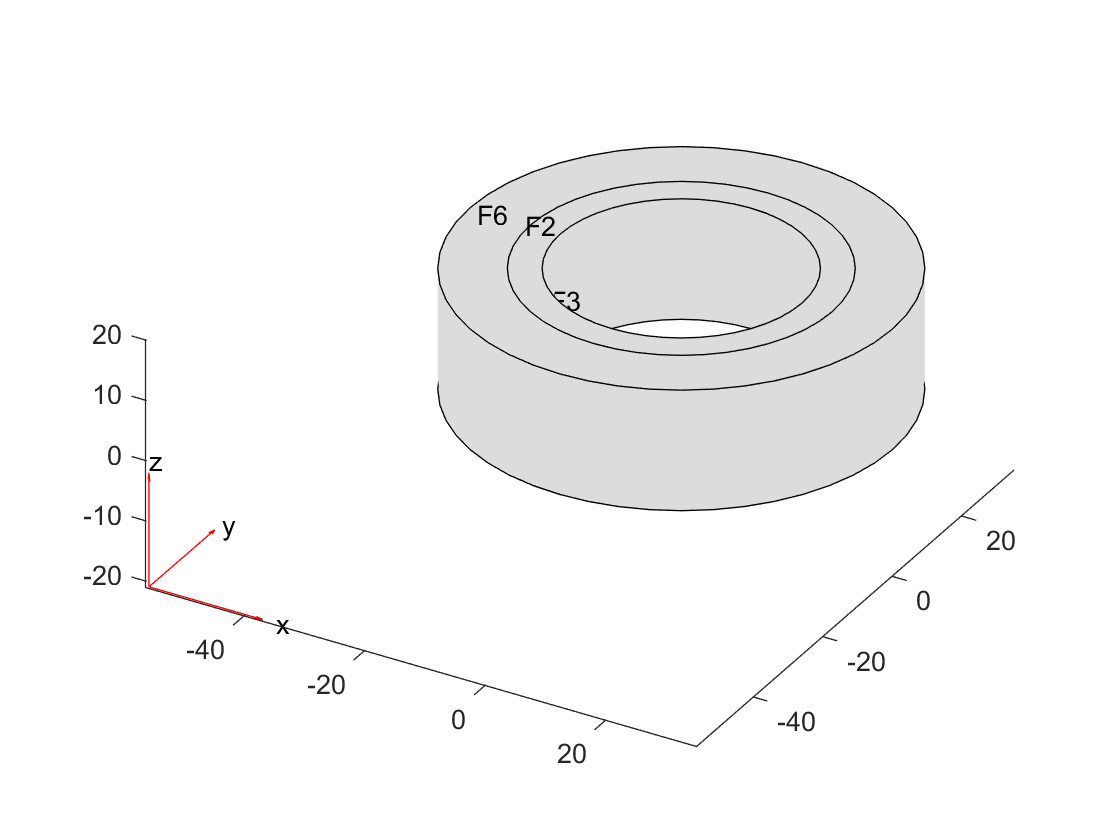

model = createpde('thermal');
geo=multicylinder([20,25,35],20,'void',[1,0,0]);
model.Geometry =geo;
pdegplot(model,'FaceLabels',"on")

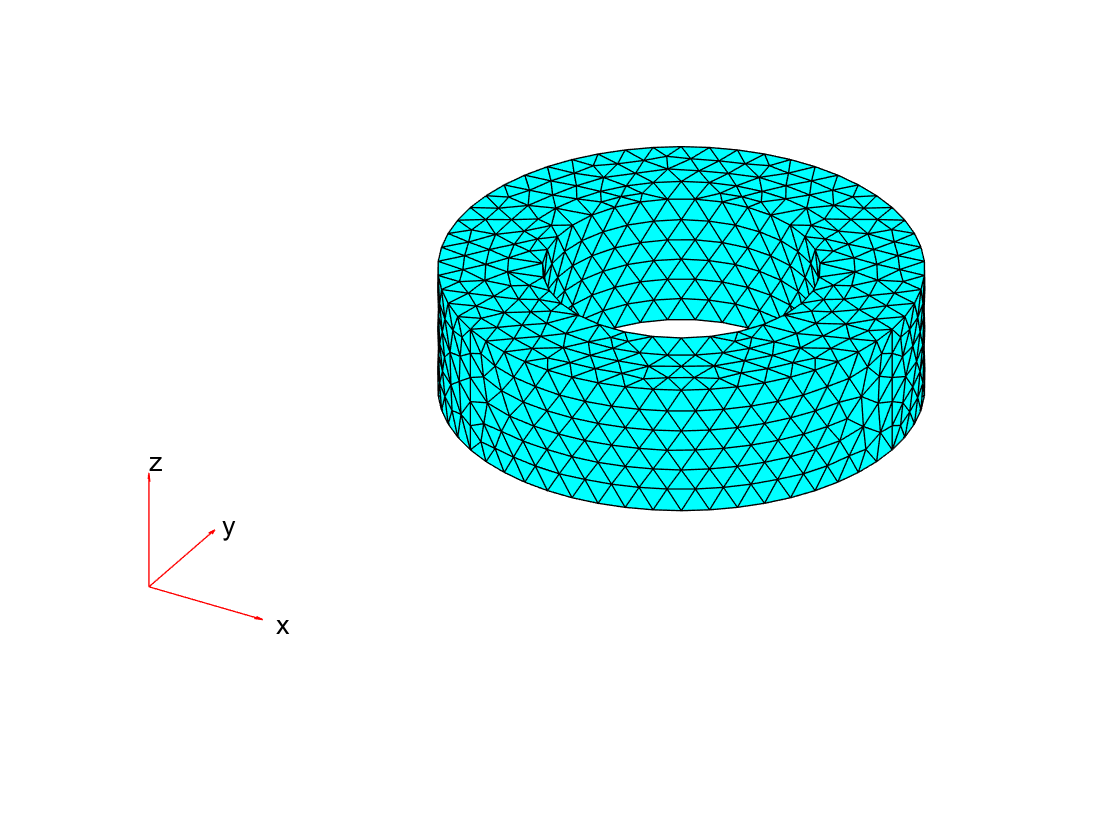


generateMesh(model);
pdemesh(model)     

设置材料；

thermalProperties(model,'Cell',1,"ThermalConductivity",40);
thermalProperties(model,'Cell',2,"ThermalConductivity",0.1);
thermalBC(model,"Face",3,"Temperature",85);
thermalBC(model,"Face",7,"Temperature",4);

结果：

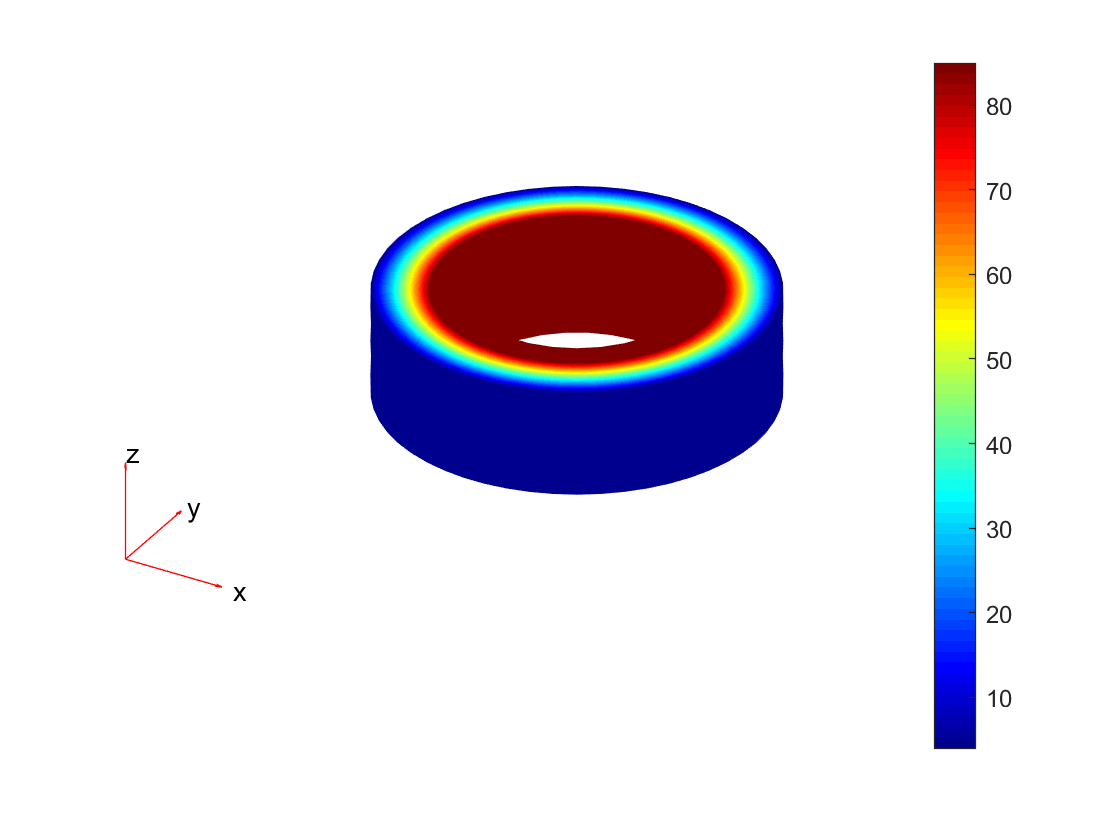

result=solve(model);
pdeplot3D(model,'ColorMapData',result.Temperature)